### Autocatalator

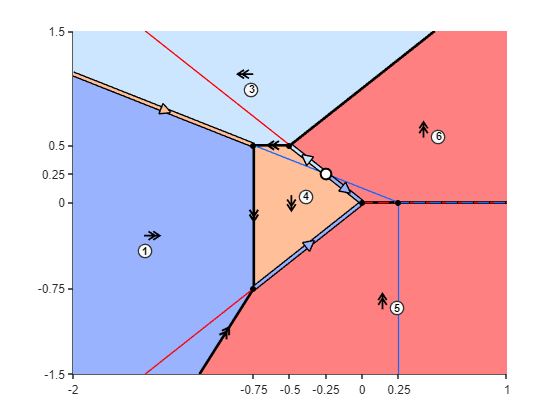

clear
close all
% f = figure("Visible","on","Units","normalized","OuterPosition",[0.1 0.1 .7 .8]);
% Parameter
a = 0.25;
% Limits:
ulim = [-2 1];
vlim = [-1.5 1.5];
% Tropical polynomials: [delta, a, n, m]
F = [1 a-1 -1 0;-1 -1 0 0; -1 -1 0 2];
G = [-1 0 0 0; 1 0 1 -1; 1 0 1 1];
TropicalPhasePlane(F,G,ulim,vlim,true)

% Draw Trajectories:
w0 = [-1 0; -0.5 0];
eps = 0.1;
% EpsilonPhasePlot(F,G,w0,eps)


### Autocatalator Bifurcations

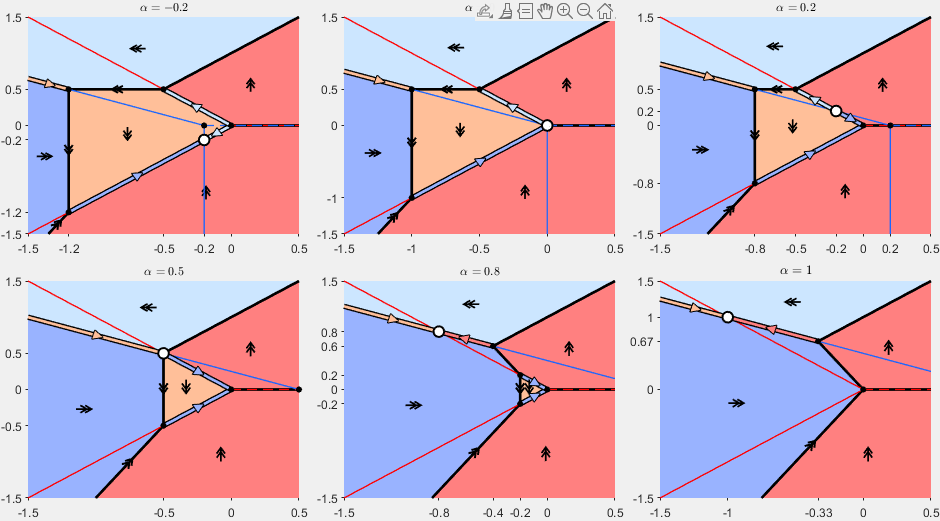

clear
close all
f = figure("Visible","on","Units","normalized","OuterPosition",[0.1 0.1 .7 .8]);
% fontsize(f,8,'points')
A = [-0.2; 0; 0.2; 0.5; 0.8; 1];
ulim = [-1.5 0.5];
vlim = [-1.5 1.5];
F = @(a) [1 a-1 -1 0;-1 -1 0 0; -1 -1 0 2];
G = @(a) [-1 0 0 0; 1 0 1 -1; 1 0 1 1];
TropicalBifurcations(3,A,"\alpha",F,G,ulim,vlim)

### Autocatalator Lifted Subdivision

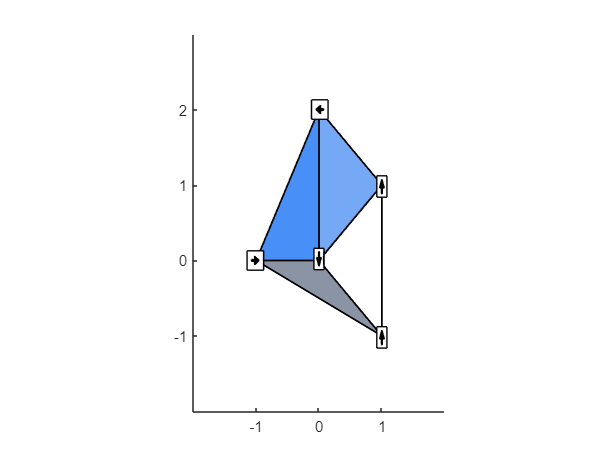

clear
close all
a = 0;
F = [1 a-1 -1 0; -1 -1 0 0; -1 -1 0 2];
G = [-1 0 0 0; 1 0 1 -1; 1 0 1 1];
[P,L] = LabelledPointConfiguration(F,G);
% Subdivision with labels:
SubdivisionHeightPlot(P,L,true)

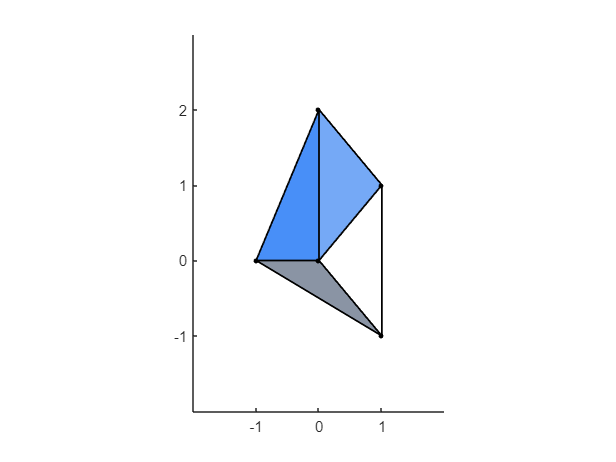

% Subdivision without labels:
figure
SubdivisionHeightPlot(P,L,false)

### Autocatalator Lifted Subdivision

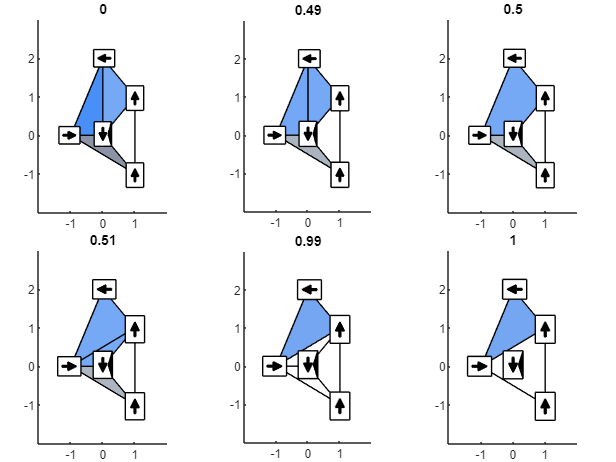

clear
close all
A = [0 0.49 0.5 0.51 0.99 1];
figure
tiledlayout(2,ceil(length(A)/2),'TileSpacing','tight','Padding','tight');
for a = A
    F = [1 a-1 -1 0; -1 -1 0 0; -1 -1 0 2];
    G = [-1 0 0 0; 1 0 1 -1; 1 0 1 1];
    [P,L] = LabelledPointConfiguration(F,G);
    nexttile
    SubdivisionHeightPlot(P,L,true)
    title(a)
end

### Minkowski sum of the u- and v-subdivisions

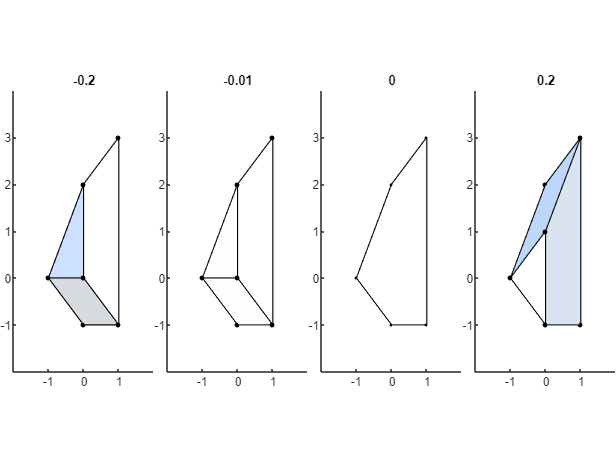

clear
close all
A = [-0.2 -0.01 0 0.2];
f = figure;
rows = 1;
tiledlayout(rows,ceil(length(A)/rows),'TileSpacing','tight','Padding','tight');
for a = A
    F = [1 a-1 -1 0; -1 -1 0 0; -1 -1 0 2];
    G = [-1 0 0 0; 1 0 1 -1; 1 0 1 1];
    Pu = [F(:,3:4), F(:,2)];
    Pv = [G(:,3:4), G(:,2)];
    dF = [F(:,1), zeros(size(F,1), 1)];
    dG = [zeros(size(G,1), 1), G(:,1)];
    dP = [dF;dG];
    [M,dD,dS] = MinkowskiSum(Pu,Pv,dF,dG);
    nexttile
    SubdivisionHeightPlot(M,dD,false)
    title(a)
end

### Minkowski sum of all three subdivisions

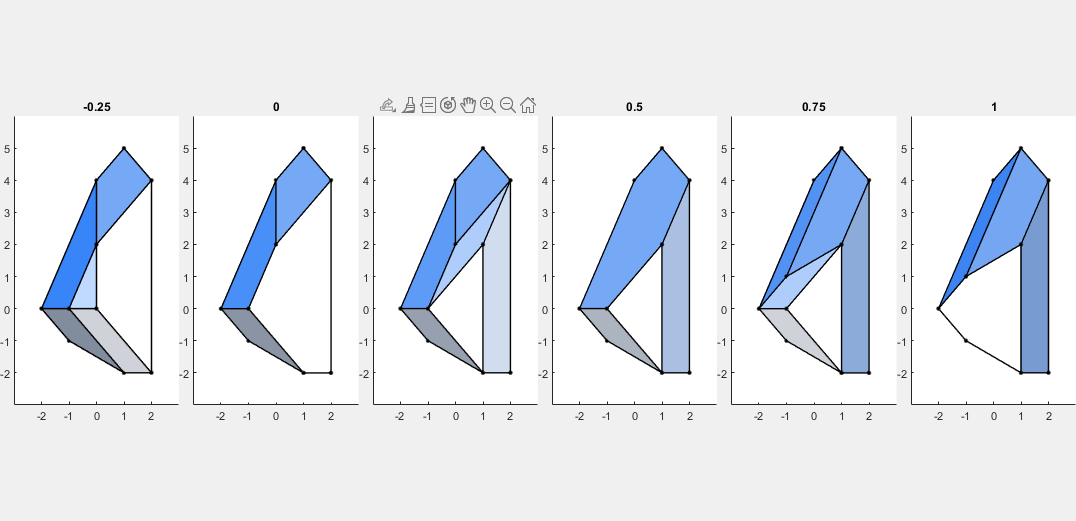

clear
close all
A = [-0.25 0 0.25 0.5 0.75 1];
f = figure("Visible","on","Units","normalized","OuterPosition",[0.1 0.1 .8 .8]);
rows = 1;
tiledlayout(rows,ceil(length(A)/rows),'TileSpacing','tight','Padding','tight');
for a = A
    F = [1 a-1 -1 0; -1 -1 0 0; -1 -1 0 2];
    G = [-1 0 0 0; 1 0 1 -1; 1 0 1 1];
    Pu = [F(:,3:4), F(:,2)];
    Pv = [G(:,3:4), G(:,2)];
    P = [Pu;Pv];
    dF = [F(:,1), zeros(size(F,1), 1)];
    dG = [zeros(size(G,1), 1), G(:,1)];
    dP = [dF;dG];
    [M1,dD1,dS1] = MinkowskiSum(Pu,Pv,dF,dG);
    [M2,dD2,dS2] = MinkowskiSum(P,M1,dP,dD1);
    nexttile
    SubdivisionHeightPlot(M2,dD2,false)
    title(a)
end

### Autocatalator Tropical Curves

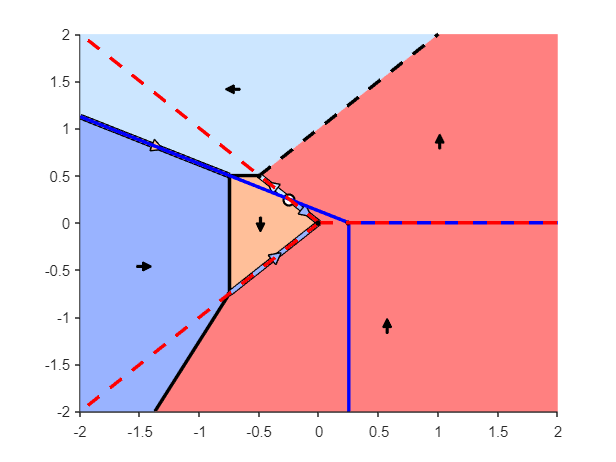

clear
close all
a = 0.25;
ulim = 2*[-1 1];
vlim = ulim;
F = [1 a-1 -1 0; -1 -1 0 0; -1 -1 0 2];
G = [-1 0 0 0; 1 0 1 -1; 1 0 1 1];
TropicalCurvesAll(F,G,ulim,vlim)

### Autocatalator Tropical Curves - Bifurcations

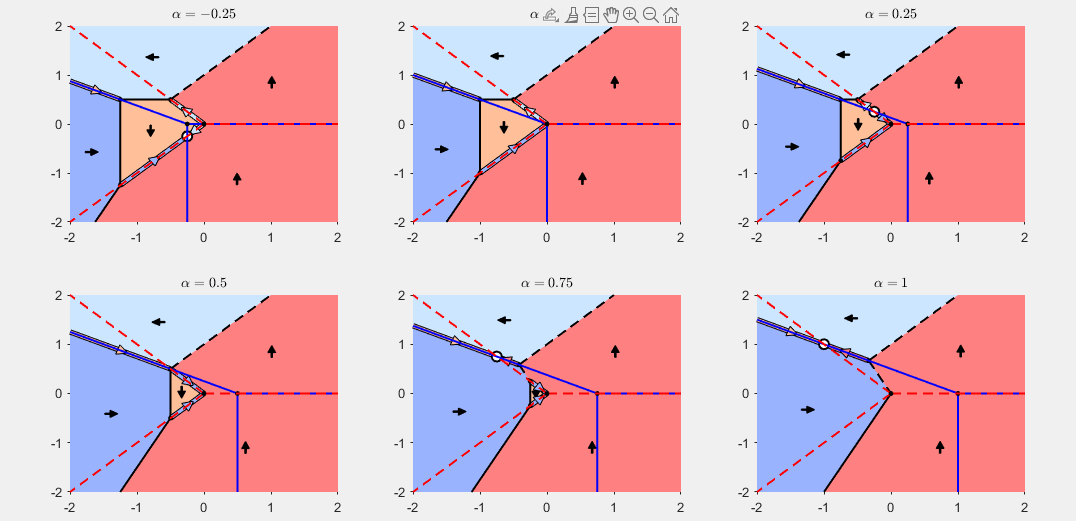

clear
close all
A = [-0.25 0 0.25 0.5 0.75 1]';
f = figure("Visible","on","Units","normalized","OuterPosition",[0.1 0.1 .8 .8]);
tiledlayout(2,ceil(length(A)/2),'TileSpacing','tight','Padding','tight');
ulim = 2*[-1 1];
vlim = ulim;
F = @(a) [1 a-1 -1 0; -1 -1 0 0; -1 -1 0 2];
G = @(a) [-1 0 0 0; 1 0 1 -1; 1 0 1 1];
TropicalCurvesBifurcations(3,A,'\alpha',F,G,ulim,vlim)